# Reverse Process

clc; clear all; close;

## Consider the SDE:

## 
$$\begin{array}{l}
{\textrm{dX}}_t =-\frac{1}{2}\beta \left(t\right)X_t d_t +\sqrt{\beta \left(t\right)}{\textrm{dW}}_t \\
X\left(0\right)~N\left(\mu_0 ,\sigma_0^2 \right)
\end{array}$$


## By Ito's formula, we can obtain

## 
$$X_t ~N\left(\mu_t ,\sigma_t^2 I\right),$$


## where

## $\mu_t =\exp \left(-\frac{1}{2}\int_0^t \beta \left(s\right)\textrm{ds}\right)\mu_0$ and $\sigma_t^2 =\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)\sigma_0^2 +1-\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)$.

## The p.d.f. is

## 
$$p\left(x,t\right)=\frac{1}{{\left(2\pi \right)}^{\frac{d}{2}} \sigma_t^d }\exp \left(-\frac{1}{2\sigma_t^2 }{\left(x-\mu_t \right)}^{\top } \left(x-\mu_t \right)\right)$$


## and we can thus compute the score function

## 
$$s\left(x,t\right)=-\frac{x-\mu_t }{\sigma_t^2 }$$


## and the "noise" function $\varepsilon \left(x,t\right)=-\tilde{\sigma} \left(t\right)s\left(x,t\right)$, where $\tilde{\sigma} {\left(t\right)}^2 =$$1-\exp \left(-\int_0^t \beta \left(s\right)\textrm{ds}\right)$is the variance from the distribution $X_t |X_0 ~N\left(\exp \left(-\frac{1}{2}\int_0^t \beta \left(s\right)\textrm{ds}\right)X_0 ,\tilde{\sigma} {\left(t\right)}^2 \right)$. In the numerical simulation, we will take $\beta \left(t\right)=t$.

%% numerical setup
T  = 10;   % terminal time
M  = 1000; % number of iterations
dt = T/M;  % time step size
N  = 2000; % number of particles
% ... exact mean and std ...
mu_0    = 2;
sigma_0 = 1.5;
% ... initial condition ...
mu  = @(t) exp(-t^2/4)*mu_0;
std = @(t) sqrt( exp(-t^2/2)*sigma_0^2 + 1 - exp(-t^2/2) );
Xh_0 = zeros(N, M+1); Xh_0(:,M+1) = normrnd(mu(T),std(T),N,1);
% ... Ornstein-Uhenbeck process ...
beta = @(t) t;
f     = @(x,t) -beta(t)/2*x;
g     = @(x,t) sqrt(beta(t));
s     = @(x,t) -( x - mu(t) )./std(t).^2;
sigma_tilde = @(t) sqrt( 1 - exp(-t^2/2) );
eps   = @(x,t) -sigma_tilde(t)*s(x,t);

## The corresponding reverse process reads

## 
$$\begin{array}{l}
d\bar{X_t } =\left(-\frac{1}{2}\beta \left(t\right)\bar{X_t } -\beta \left(t\right)s\left(\bar{X_t } ,t\right)\right)+\sqrt{\beta \left(t\right)}{\textrm{dW}}_t \\
\;\;\;\;\;\;\;=\left(-\frac{1}{2}\beta \left(t\right)\bar{X_t } +\beta \left(t\right)\frac{\varepsilon \left(\bar{X_t } ,t\right)}{\tilde{\sigma} \left(t\right)}\right)+\sqrt{\beta \left(t\right)}{\textrm{dW}}_t 
\end{array}$$


## So the Euler-Maruyama reverse process reads

## ${\bar{X} }_{k-1} ={\bar{X} }_k +\left(-\frac{1}{2}\beta \left(t_k \right)\bar{X_k } +\beta \left(t_k \right)\frac{\varepsilon \left({\bar{X} }_k ,t_k \right)}{\tilde{\sigma} \left(t_k \right)}\right)\left(-\Delta t\right)+\sqrt{\beta \left(t_k \right)}\sqrt{\Delta t}Z$, where $Z~N\left(0,I\right)$

% Euler-Maruyama method (backward)

for i = M:-1:1
   ti = i*dt;
%    Xh_0(:,i) = Xh_0(:,i+1) + ( f(Xh_0(:,i+1),ti) - g(Xh_0(:,i+1),ti).^2.*s(Xh_0(:,i+1),ti) )*(-dt) ...
%              + g(Xh_0(:,i+1),ti)*sqrt(dt)*randn(N,1);

   Xh_0(:,i) = ( 1 + 1/2*beta(ti)*dt )*Xh_0(:,i+1) - beta(ti)*dt/sigma_tilde(ti)*eps(Xh_0(:,i+1),ti) + ...
               + sqrt( beta(ti)*dt )*randn(N,1);

%    Xh_0(:,i) = 1/sqrt( 1 - beta(ti)*dt )*Xh_0(:,i+1) - beta(ti)*dt/std(ti)*eps(Xh_0(:,i+1),ti) + ...
%                + sqrt( beta(ti)*dt )*randn(N,1);

end

## We then compute the mean and std

mu_sde  = sum(Xh_0(:,1))/N;
std_sde = sqrt( sum((Xh_0(:,1)-mu_sde).^2)/N );

## Finally, output the numerical mean and std

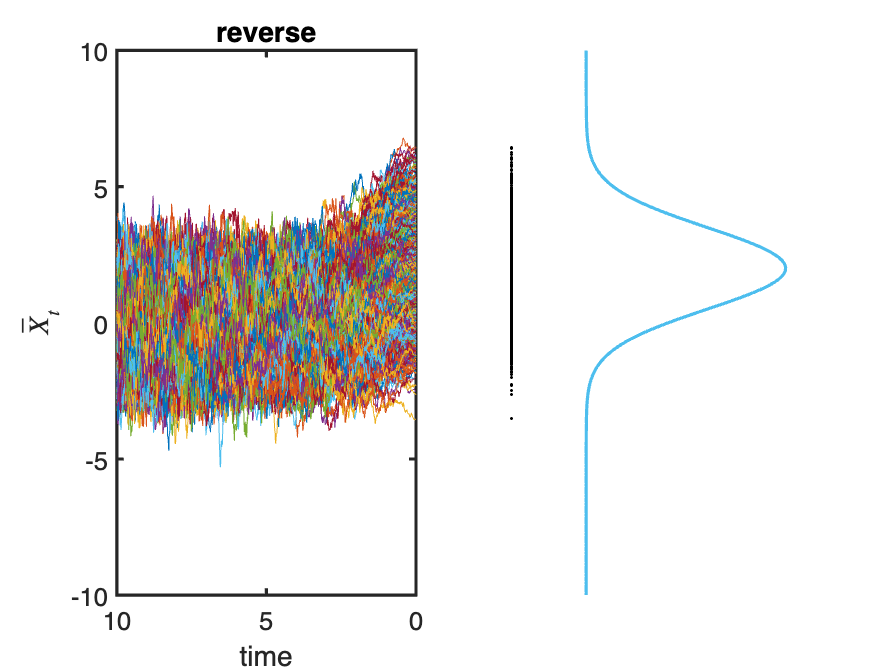

%% Output
subplot(1,2,1);
plot(0:dt:T,Xh_0); ylim([-10,10]); xlabel('time'); ylabel('$\bar{X}_t$','Interpreter','latex');
set(gca,'FontSize',16,'LineWidth',2, 'XDir','reverse'); title('reverse');
subplot(1,2,2);
plot(-0.1,Xh_0(:,1),'k.',normpdf(-10:0.1:10,mu_0,std(0)),-10:0.1:10,'LineWidth',2);
axis off;

disp(['exact.mean = ', num2str(mu_0,'%.6f')]);

exact.mean = 2.000000


disp(['numer.mean = ', num2str(mu_sde,'%.6f')]);

numer.mean = 1.938911


disp(['exact.std  = ', num2str(std(0),'%.6f')]);

exact.std  = 1.500000


disp(['numer.std  = ', num2str(std_sde,'%.6f')]);

numer.std  = 1.506583
